# t_bpTemporal

Illustrate the bipolar temporal filters.

BW ISETBIO Team, 2016

ieInit

## Create a small cone mosaic

This mosaic is used for its temporal absorptions.  Spacing doesn't matter for this calculation.


% Small mosaic.
rows = 5; cols = 5; tSamples = 100;
cMosaic = coneMosaic('size',[rows,cols]);

% Dummy up some absorptions.
cMosaic.absorptions = single(randi(10,rows,cols,tSamples));   
cMosaic.integrationTime = 0.002;
cMosaic.emGenSequence(tSamples);

% If you want to look ...
%   cMosaic.window;

## Compute the os linear filters and the bipolar

By default, on creation the bipolar mosaic creates a filter so that os convolved with bipolar matches the Pillow RGC filter.  We have a plan to do this differently in the future.  In particular, we would like to define a default like that but also make it easy to select different filters. 


cMosaic.os.linearFilters(cMosaic);
cMosaic.computeCurrent;             % Calculates the photocurrent impulse response

% Make the bipolar layer and one mosaic
bpL = bipolarLayer(cMosaic);
ii = 1;
bpL.mosaic{ii} = bipolarMosaic(cMosaic,'on midget');
bpL.mosaic{ii}.compute;             % Calculates the impulse response

% To look
%   bpL.window;

## Comment

If you used a cMosaic with a real time varying signal, then you can do this to see the bipolar filter at the cone mosaic sample.  These two plots differ because the cMosaic time axis only runs to 200 ms.  The OS goes out to 400 ms.  We need to deal with the ringing at the end of the bipolar filter!! (BW)

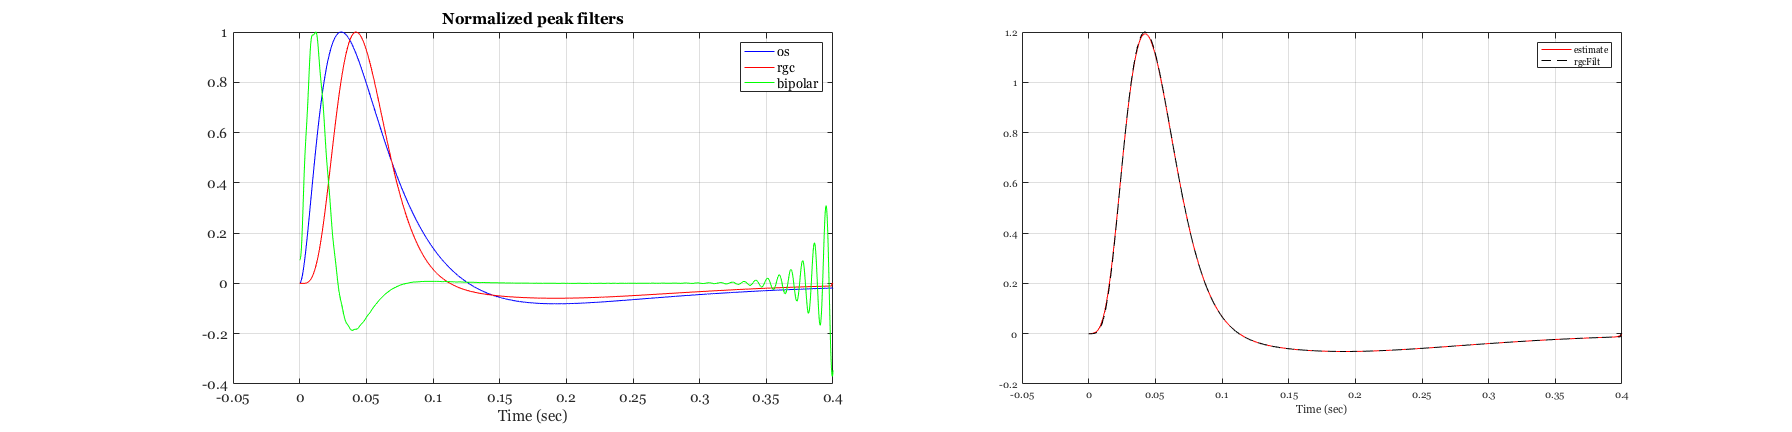


% Shows a longer amount of time
bpFilter = bipolarFilter(bpL.mosaic{ii}, cMosaic,'graph',true);

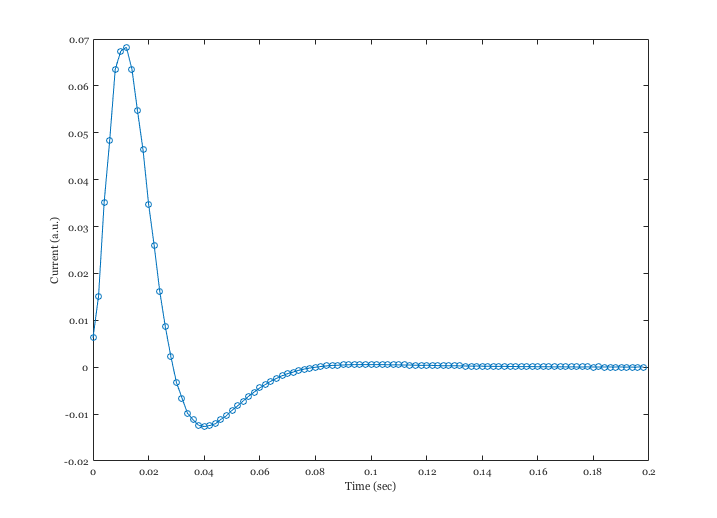


% The first part is OK.  The last temporal part has a problem with ringing.
vcNewGraphWin; plot(cMosaic.timeAxis,bpFilter,'o-'); 

xlabel('Time (sec)'); ylabel('Current (a.u.)')
